# Finite Element Formulation of the Plane Stress Membrane Case - Uniformly Distributed Load and Clamped Corners

## Introduction

In this section it is considered a shear-deformable plate that is fixed at two corners of its boundary (Dirichlet boundary conditions) whereas a uniformly distributed boundary load is applied along its surface boundary, see the following figure accordingly:

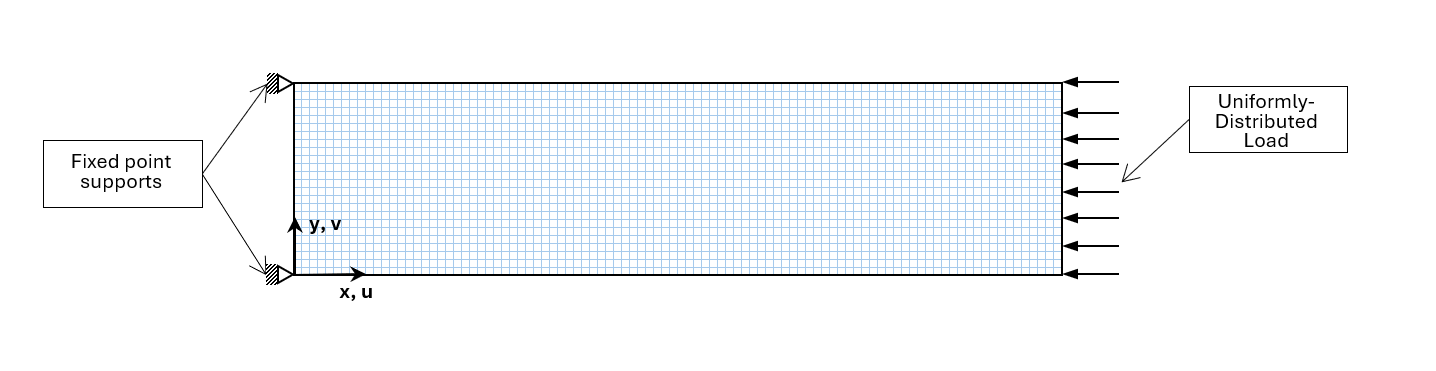

This kind of problem can be mathematically described using the plane stress membrane theory. The primal uknown fields of the membrane are the displacements of the midplane of the membrane u(x,y) (the displacement along the x-axis) and v(x,y) (the displacement along the y-axis). The underlying Partial Differential Equation (PDE) writes as follows:


$$\begin{array}{lll}
\frac{\partial n_x}{ \partial x} + \frac{\partial n_{yx}}{ \partial y} + p_x = 0, & \text{in} \: \Omega, & \text{(1.1)} \\
\frac{\partial n_y}{ \partial y} + \frac{\partial n_{xy}}{ \partial x} + p_y = 0, & \text{in} \: \Omega, & \text{(1.2)} \\
n_{xy} = n_{yx}, & \text{in} \: \Omega, & \text{(1.3)} \\
\\
n_x = p_x,                         & \text{on} \: \subset \partial \Omega_x, & \text{(1.4)} \\
n_{xy} = p_y,                         & \text{on} \: \subset \partial \Omega_x, & \text{(1.4)} \\
n_y = 0,            & \text{on} \: \subset \partial \Omega_y, & \text{(1.4)} \\
n_{xy} = 0,              & \text{on} \: \subset \partial \Omega_y, & \text{(1.4)} \\
\end{array}$$


The corresponding strains are given by the following expressions:


$$\begin{array}{ll}
\varepsilon_x = \frac{\partial u}{\partial x}     & \text{(2.1)} \\
\varepsilon_y = \frac{\partial v}{\partial y}      & \text{(2.2)} \\
\gamma_{xy} = \frac{\partial u}{\partial y} + \frac{\partial v}{\partial x}                      & \text{(2.3)} \\
\end{array}$$


Then, the constitutive equations are given by the following relations:


$$\begin{array}{ll}
n_x = D(\varepsilon_x + \nu\varepsilon_y)         & \text{(3.1)} \\
n_y = D(\varepsilon_y + \nu\varepsilon_x)             & \text{(3.2)} \\
n_{xy} = Gt\gamma_{xy}              & \text{(3.3)} \\
\\ \text{where:} \\
D = \frac{Et}{1-\nu^2} \\
\end{array}$$


Finally, the weak formulation of the problem writes as follows:


$$\begin{array}{ll}
\delta W_{\text{int}} + \delta W_{\text{ext}} = 0, & \text{(4.1)} \\
-\delta W_{\text{int}} = \int_{A} n_x \: \delta \varepsilon_x + n_y \: \delta \varepsilon_y + 2\cdot n_{xy} \: \delta \gamma_{xy} \: \text{d} A , & \text{(4.2)} \\
\delta W_{\text{ext}} = \int_{\subset\partial A} p_x \: \delta u \: \text{d} \partial A + \int_{\subset\partial A} p_y \: \delta v \: \text{d} \partial A . & \text{(4.3)}
\end{array}$$


syms u(x,y) v(x,y) x  y
syms eps_x(x,y) eps_y(x,y) gamma_xy(x,y)

eps_x(x,y) = diff(u(x,y),x);
eps_y(x,y) = diff(v(x,y),y);
gamma_xy(x,y) = diff(u(x,y),y) + diff(v(x,y),x);

syms n_x(x,y) n_y(x,y) n_xy(x,y) D nu G t
n_x(x,y) = D*(eps_x(x,y) + nu*eps_y(x,y));
n_y(x,y) = D*(eps_y(x,y) + nu*eps_x(x,y));
n_xy(x,y) = G*t*gamma_xy(x,y);

syms p_x p_y
equilibirum_equations = [diff(n_x(x,y),x) + diff(n_xy(x,y),y) + p_x
    diff(n_y(x,y),y) + diff(n_xy(x,y),x) + p_y];

## Preamble

clc;
clear;
close all;

## **Problem setup**

### Geometric parameters

Thickness [$m$]

propStr.t = 10^(-0.5);

X-coordinate of the left edge [$m$]

propStr.X0 = 0;

X-coordinate of the right edge [$m$]

propStr.XLx = 2;

Y-coordinate of the left edge [$m$]

propStr.Y0 = 0;

Y-coordinate of the right edge [$m$]

propStr.YLy = 0.5;

### Material paramerters

uniformly distributed load in the x-direction along the boundary at X = XLx [$N/m^2$]

propStr.p_x = -100000; 

uniformly distributed load in the y-direction along the boundary at X = XLx [$N/m^2$]

propStr.p_y = 0;

Young's modulus [$N/m^2$]

propStr.E = 33*1e9; % for concrete class C30/37 %1e7;

Poisson ration [dimensionless]

propStr.nu = 0.2; % for concrete class C30/37 %0.3;

Shear modulus (connected to `epsilon_12 = E/(1+nu)`) [$N/m^2$]

propStr.G = 13333.33*1e6; % for concrete class C30/37 

Plate stiffness [$N\cdot m$]

propStr.D = propStr.E*propStr.t/(1 - propStr.nu^2);

## **Basis functions**

### **Bilinear basis functions**


$$N_1^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 - \eta) \quad (\xi,\eta) \in [-1, 1]^2, \quad (8.1) \\
N_2^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 - \eta) \quad (\xi,\eta) \in [-1, 1]^2, \quad (8.2) \\
N_3^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 + \eta) \quad (\xi,\eta) \in [-1, 1],^2 \quad (8.3)\\
N_4^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 + \eta) \quad (\xi,\eta) \in [-1, 1]^2. \quad (8.4)$$
 

#### Definition

syms N1Q1(xi, eta) N2Q1(xi, eta) N3Q1(xi, eta) N4Q1(xi, eta)
N1Q1(xi, eta) = (1 - xi)*(1 - eta)/4;
N2Q1(xi, eta) = (1 + xi)*(1 - eta)/4;
N3Q1(xi, eta) = (1 + xi)*(1 + eta)/4;
N4Q1(xi, eta) = (1 - xi)*(1 + eta)/4;
NQ1 = {N1Q1 N4Q1 N3Q1 N2Q1};

## **Discretization**

Both fields are discretized using the same basis (shape) functions, namely:


$$\begin{array}{l}
u\left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;u_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 1\right)\\
v\left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;v_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(12\ldotp 2\right)
\end{array}$$


Here $N$ indicates the total number of nodes in the mesh. Moreover a Buvnov-Galerkin discretization is used, meaning that both the test and the unknown fields are discretized using the same basis (shape) functions.

### Quadrilateral mesh

#### Choose number of elements in the mesh

Number of elements along the X-direction

numElx = 10;

Number of elements along the Y-direction

numEly = 5;

#### Mesh generation

numEl = numElx*numEly;
[nodesX, nodesY] = generateQuadrilateralMesh ...
    (propStr.X0, propStr.XLx, propStr.Y0, propStr.YLy, numElx, numEly);

### **Four-noded bilinear quadrilateral mesh**

#### **Mesh generation**

numNodesElQ1 = 4;
mshQ1 = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesElQ1);
numNodesQ1 = numel(mshQ1.nodes(:, 1));

#### Dirichlet boundary conditions for the mesh with the bilinear quadrilateral elements

numDOFsQ1 = 2*numNodesQ1;

freeDOFsQ1 = 1:length(mshQ1.nodes(:,1))*2;
homDOFsQ1 = zeros(4,1);
homDOFsQ1(1:2) = [1;2];
homDOFsQ1(3:4) = [(numEly+1)*2-1; (numEly+1)*2];
freeDOFsQ1(homDOFsQ1) = [];

## Master stiffness matrix and load vector

### Four-noded bilinear plane stress elements

[KQ1, FQ1] = computeMasterStiffMatrixandForceVectorPlaneStress ...
    (mshQ1, NQ1, propStr);

Visualization of the sparsity of the master global stiffness matrix

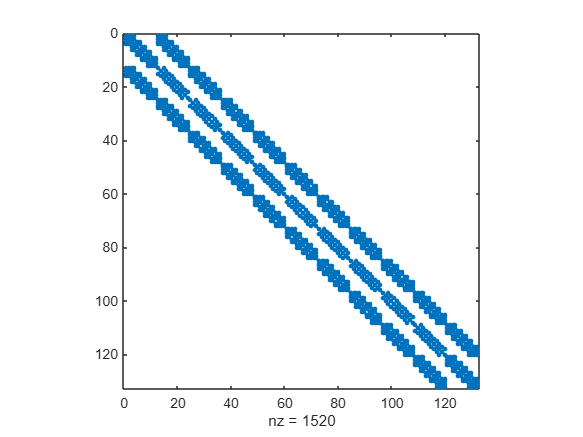

spy(KQ1)

## Solution of the plane stress problem

### Four-noded bilinear elements

#### Solution of the linear equation system

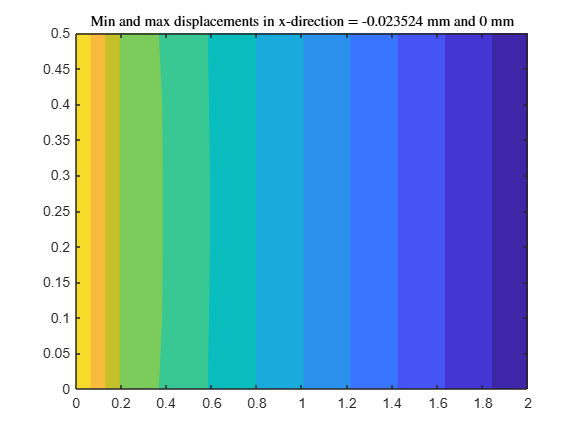

uQ1 = zeros(numDOFsQ1, 1);
uQ1(freeDOFsQ1) = KQ1(freeDOFsQ1, freeDOFsQ1)\FQ1(freeDOFsQ1);
u_x = uQ1(1:2:end)*1000; %in mm
u_y = uQ1(2:2:end)*1000; % in mm
InternalForcesQ1 = KQ1*uQ1;

XNodesPlot = mshQ1.nodes(:,1);
YNodesPlot = mshQ1.nodes(:,2);
[X,Y]=meshgrid(XNodesPlot,YNodesPlot);
Z = griddata(XNodesPlot, YNodesPlot, u_x, X, Y);
[M,c] = contourf(X,Y,Z,"EdgeColor","none");
title("Min and max displacements in x-direction = "+ min(u_x) + " mm and " + max(u_x) + " mm", Interpreter="latex")
hold off

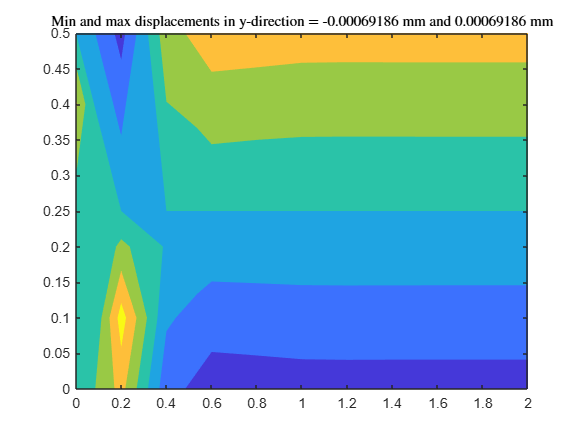

Z = griddata(XNodesPlot, YNodesPlot, u_y, X, Y);
contourf(X,Y,Z,"EdgeColor","none")
title("Min and max displacements in y-direction = "+ min(u_y) + " mm and " + max(u_y) + " mm" , Interpreter="latex")

#### Solution from FEM software for a 300mm thick plate:

Displacement in the x-direction (equivalent to the positive y-direction in software):

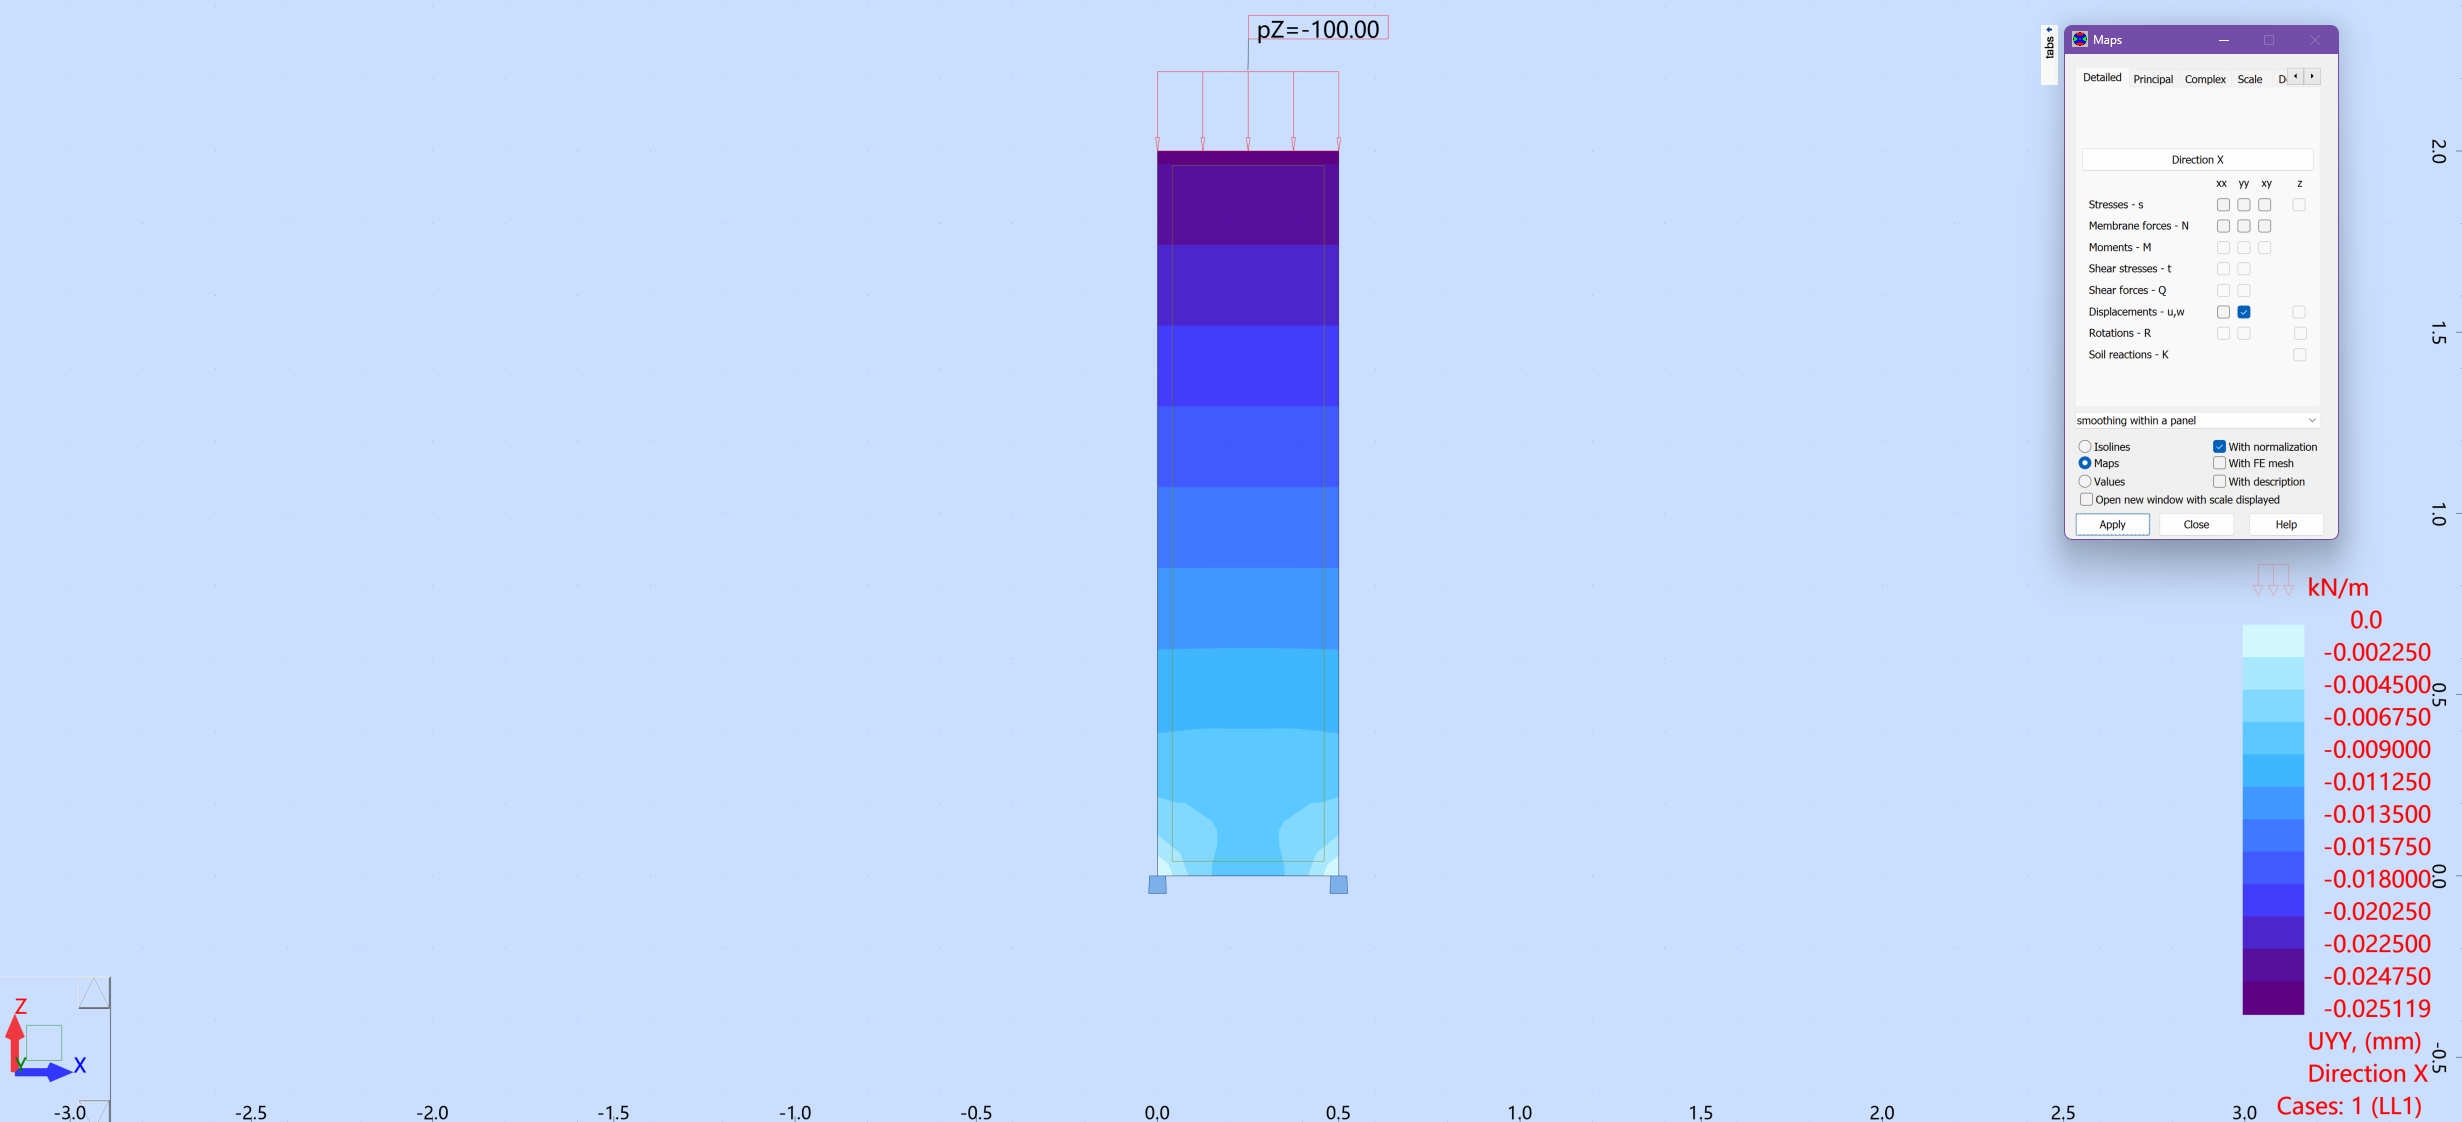

Displacement in the y-direction (equivalent to the negative x-direction in software):

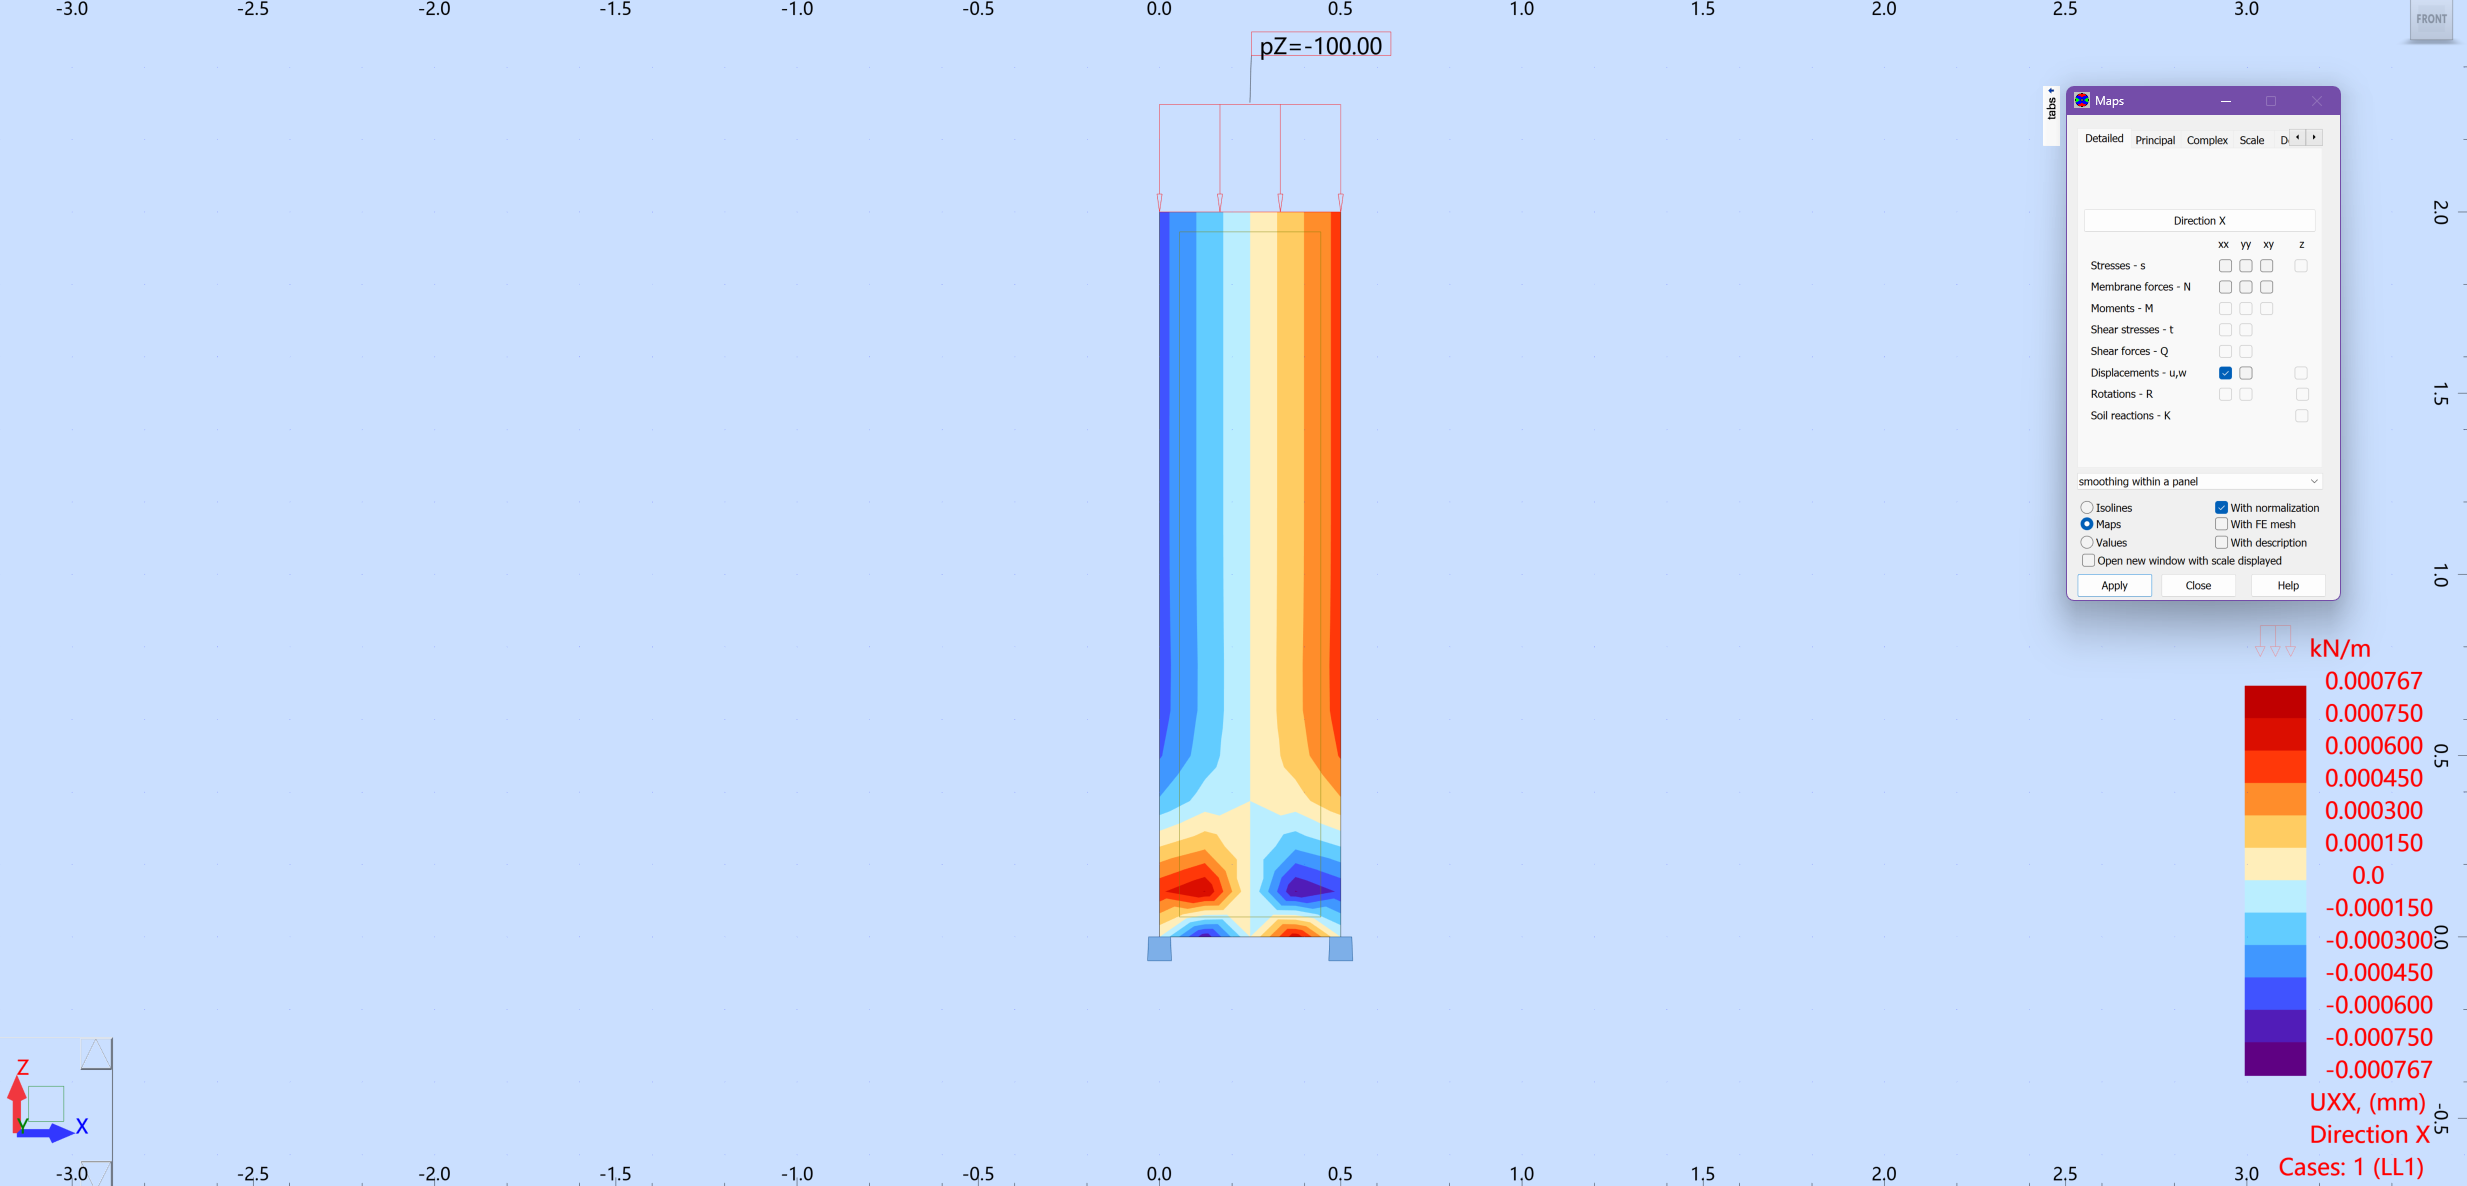

#### Extreme displacements from commercial FEM software:

minX_FEM = -0.025119;
minY_FEM = -0.000767;
maxY_FEM = 0.000767;

% error in results between results from code and commercial FEM software
Error = [(min(u_x)-minX_FEM)/min(u_x)
    (min(u_y)-minY_FEM)/min(u_y)
    (max(u_y)-maxY_FEM)/max(u_y)]*100

Error =    -6.7804
  -10.8613
  -10.8613


## Load Path Calculation

### Calculation of Strain Energy, U, of Total System 


$$P = K\cdot d\\
U_{total}  = \frac {1}{2} P_A \cdot d_A\\
U_{total} = \frac {1}{2}(K\cdot d)\cdot d_A$$


Free nodes are those that do not have support conditions or applied loading.

    DOFsfreeNodes = freeDOFsQ1(1:end-(numEly+1)*2);

    NumNodesTotal = 1:length(mshQ1.nodes(:,1));
    LoadNodes = NumNodesTotal(end-numEly:end);
    SupportNodes = [1; numEly+1];
    FreeNodes = NumNodesTotal;
    FreeNodes(LoadNodes) = [];
    FreeNodes(SupportNodes) = [];

    DOFS_load_nodes = freeDOFsQ1;
    DOFS_load_nodes = DOFS_load_nodes(DOFS_load_nodes>max(DOFsfreeNodes));
    DOFS_support_nodes = homDOFsQ1;
    NumberOfFreeNodesQ1 = length(DOFsfreeNodes)/2;



    u_total_known = [uQ1(homDOFsQ1); uQ1(DOFS_load_nodes)];
    KQ1_total = KQ1;
    KQ1_total(DOFS_load_nodes,:) = [];
    KQ1_total(homDOFsQ1,:) = [];

    KQ1_total_known_displ = KQ1_total(:, [transpose(homDOFsQ1), DOFS_load_nodes]);
    FQ1_total_known_displ = -1*(KQ1_total_known_displ*u_total_known);

    KQ1_total(:,DOFS_load_nodes) = [];
    KQ1_total(:,homDOFsQ1) = [];

    u_total_unknown = KQ1_total\FQ1_total_known_displ;
    uQ1_total_nodes = [uQ1(homDOFsQ1); u_total_unknown; uQ1(DOFS_load_nodes)];
    U_index_total = (1/2)*transpose(KQ1*uQ1_total_nodes)*uQ1_total_nodes

U_index_total = 0.6336

Calculating U for the total system simply by using the calculated displacements:

    U_index_total = (1/2)*transpose(KQ1*uQ1)*uQ1

U_index_total = 0.5881

### Calculation of Strain Energy, U, For Each Node

    U_fixed_node = zeros(NumberOfFreeNodesQ1,1);
    U_index_fixed_node = zeros(NumberOfFreeNodesQ1,1);

    u_iterative = zeros(length(uQ1),length(FreeNodes));   % the displacement vector from each iteration done to calculate the U* values
    F_iterative = zeros(length(uQ1),length(FreeNodes)); 

Using an updated displacement vector by solving for each system:

    u_known = [zeros(6,1); uQ1(DOFS_load_nodes)];
    for kk = 1:length(FreeNodes)
        fixedNodeDOF1 = (FreeNodes(kk)*2-1);

        if FreeNodes(kk) < max(SupportNodes)

            KQ1_fixed_node = KQ1;
            KQ1_fixed_node(DOFS_load_nodes,:) = [];
            KQ1_fixed_node(homDOFsQ1(3:4),:) = [];
            KQ1_fixed_node(fixedNodeDOF1:fixedNodeDOF1+1,:) = [];
            KQ1_fixed_node(homDOFsQ1(1:2),:) = [];

            KQ1_known_displ = KQ1_fixed_node(:, [transpose(homDOFsQ1(1:2)),fixedNodeDOF1:fixedNodeDOF1+1,transpose(homDOFsQ1(3:4)),DOFS_load_nodes]);
            FQ1_known_displ = -1*(KQ1_known_displ * u_known);

            KQ1_fixed_node(:,DOFS_load_nodes) = [];
            KQ1_fixed_node(:,homDOFsQ1(3:4)) = [];            
            KQ1_fixed_node(:,fixedNodeDOF1:fixedNodeDOF1+1) = [];
            KQ1_fixed_node(:,homDOFsQ1(1:2)) = [];
        else 
            KQ1_fixed_node = KQ1;
            KQ1_fixed_node(DOFS_load_nodes,:) = [];
            KQ1_fixed_node(fixedNodeDOF1:fixedNodeDOF1+1,:) = [];
            KQ1_fixed_node(homDOFsQ1,:) = [];
                    
            KQ1_known_displ = KQ1_fixed_node(:, [transpose(homDOFsQ1),fixedNodeDOF1:fixedNodeDOF1+1,DOFS_load_nodes]);
            FQ1_known_displ = -1*(KQ1_known_displ * u_known);

            KQ1_fixed_node(:,DOFS_load_nodes) = [];
            KQ1_fixed_node(:,fixedNodeDOF1:fixedNodeDOF1+1) = [];
            KQ1_fixed_node(:,homDOFsQ1) = [];
        end


        u_unknown = KQ1_fixed_node\FQ1_known_displ;


        if fixedNodeDOF1 == 3
            uQ1_fixed_node = [uQ1(homDOFsQ1(1:2)); zeros(2,1); u_unknown(1:homDOFsQ1(3)-5); uQ1(homDOFsQ1(3:4)); u_unknown(homDOFsQ1(3)-4:end); uQ1(DOFS_load_nodes)];
        elseif fixedNodeDOF1 > 3 && fixedNodeDOF1 < homDOFsQ1(3)-2
            uQ1_fixed_node = [uQ1(homDOFsQ1(1:2)); u_unknown(1:fixedNodeDOF1-3); zeros(2,1); u_unknown(fixedNodeDOF1-2:homDOFsQ1(3)-5); uQ1(homDOFsQ1(3:4)); u_unknown(homDOFsQ1(3)-4:end); uQ1(DOFS_load_nodes)];
        elseif fixedNodeDOF1 == homDOFsQ1(3)-2
            uQ1_fixed_node = [uQ1(homDOFsQ1(1:2)); u_unknown(1:homDOFsQ1(3)-5); zeros(2,1); uQ1(homDOFsQ1(3:4)); u_unknown(homDOFsQ1(3)-4:end); uQ1(DOFS_load_nodes)];

        elseif fixedNodeDOF1 == max(homDOFsQ1)+1
            uQ1_fixed_node = [uQ1(homDOFsQ1(1:2)); u_unknown(1:homDOFsQ1(3)-3); uQ1(homDOFsQ1(3:4)); zeros(2,1); u_unknown(homDOFsQ1(3)-2:end); uQ1(DOFS_load_nodes)];
        elseif fixedNodeDOF1 == min(DOFS_load_nodes)-2
            uQ1_fixed_node = [uQ1(homDOFsQ1(1:2)); u_unknown(1:homDOFsQ1(3)-3); uQ1(homDOFsQ1(3:4)); u_unknown(homDOFsQ1(3)-2:end); zeros(2,1); uQ1(DOFS_load_nodes)];
        else
            uQ1_fixed_node = [uQ1(homDOFsQ1(1:2)); u_unknown(1:homDOFsQ1(3)-3); uQ1(homDOFsQ1(3:4)); u_unknown(homDOFsQ1(3)-2:fixedNodeDOF1-length(homDOFsQ1)-2,1); zeros(2,1); u_unknown(fixedNodeDOF1-length(homDOFsQ1)-1:end); uQ1(DOFS_load_nodes)];
        end
        
        u_iterative(:,kk) = uQ1_fixed_node;
        F_iterative(:,kk) = KQ1*uQ1_fixed_node;


        U_fixed_node(kk) = (1/2)*transpose(KQ1*uQ1_fixed_node)*uQ1_fixed_node;
        U_index_fixed_node(kk) = 1- U_index_total/U_fixed_node(kk);

    end


    U_index = zeros(length(mshQ1.nodes(:,1)),1);
    U_index(2:SupportNodes(2)-1) = U_index_fixed_node(1:length(2:SupportNodes(2)-1));
    U_index(SupportNodes(2)+1:max(FreeNodes)) = U_index_fixed_node(length(2:SupportNodes(2)):end);
    U_index(LoadNodes) = 1;

Visualization of load path

XNodesPlot = mshQ1.nodes(:,1);
YNodesPlot = mshQ1.nodes(:,2);

[X,Y]=meshgrid(XNodesPlot,YNodesPlot);
Z = griddata(XNodesPlot, YNodesPlot, U_index, X, Y);
figure;
[C, hCont] = contourf(X,Y,Z,'linecolor','none','LineWidth',0.01,"ShowText","on","LabelSpacing",600);
daspect([2 2 2]);
[hLeg, levMat] = contourLegend(hCont);
hLeg.Location = 'southeastoutside'; 
hLeg.FontSize = 7;
hold on

U_x_grad = gradient(U_index,XNodesPlot);
U_x_grad(isinf(U_x_grad)) = 1;
U_x_grad(isnan(U_x_grad)) = 0;
U_y_grad = gradient(U_index,YNodesPlot);


### Using streamlines

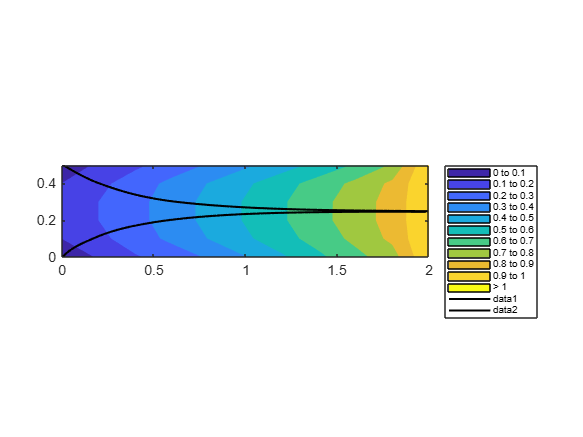

[startX,startY] = meshgrid(propStr.X0+0.003,mshQ1.nodes(SupportNodes,2));
X_unique = unique(mshQ1.nodes(:,1));
Y_unique = unique(mshQ1.nodes(:,2));
UX = reshape(U_x_grad,numEly+1,numElx+1);
UY = reshape(U_y_grad,numEly+1,numElx+1);
[XGrid, YGrid] = meshgrid(X_unique,Y_unique);

lineobj = stream2(XGrid, YGrid,UX,UY,startX,startY);

lineobj = streamline(lineobj);
lineobj(1).Color = "k";
lineobj(2).Color = "m";
for i = 1:length(lineobj)
    lineobj(i).Color = "k";
    lineobj(i).LineWidth = 1.5;

end

[startX_inv,startY_inv] = meshgrid(propStr.XLx-0.01,mshQ1.nodes(LoadNodes,2));
verts_inv = stream2(XGrid, YGrid,-UX,-UY,startX_inv,startY_inv);
% lineobj_inv = streamline(verts_inv);
% for i = 1:length(lineobj_inv)
%     lineobj_inv(i).Color = "#7E2F8E";
%     lineobj_inv(i).LineWidth = 2;
% end

hold off

Streamlines properties:

linobj1 = lineobj(1);
linobj2 = lineobj(2);

linobj1X = linobj1.XData;
linobj1Y = linobj1.YData;

linobj2X = linobj2.XData;
linobj2Y = linobj2.YData;

Streamline lengths, found using Pythagoran theorem:

n1 = numel(linobj1X);
length1 = 0;
for i = 1:n1-1
    length1 = length1 + sqrt( (linobj1X(i+1)-linobj1X(i))^2 + (linobj1Y(i+1)-linobj1Y(i))^2 );
end
n2 = numel(linobj2X);
length2 = 0;
for i = 1:n2-1
    length2 = length2 + sqrt( (linobj2X(i+1)-linobj2X(i))^2 + (linobj2Y(i+1)-linobj2Y(i))^2 );
end

Streamline curvatures:

C1 = LineCurvature2D([transpose(linobj1X),transpose(linobj1Y)]);
C2 = LineCurvature2D([transpose(linobj2X),transpose(linobj2Y)]);


### Using streamslice

Flow from supports to load nodes:

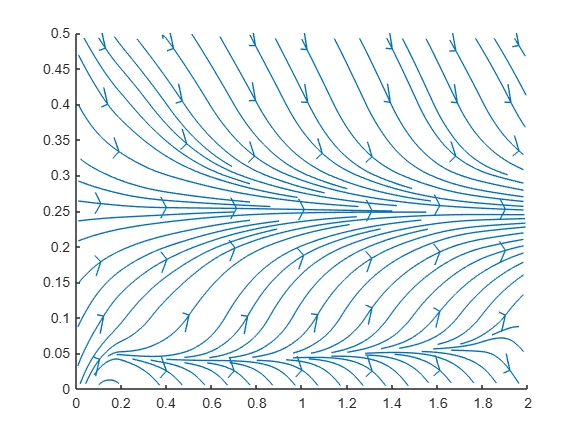

figure;
[sliceverts, sliceaverts] = streamslice(XGrid, YGrid,UX,UY);
slicelinobj = streamslice(XGrid, YGrid,UX,UY);
xlim([propStr.X0,propStr.XLx])
ylim([propStr.Y0,propStr.YLy])
hold off

Flow from load nodes to supports:

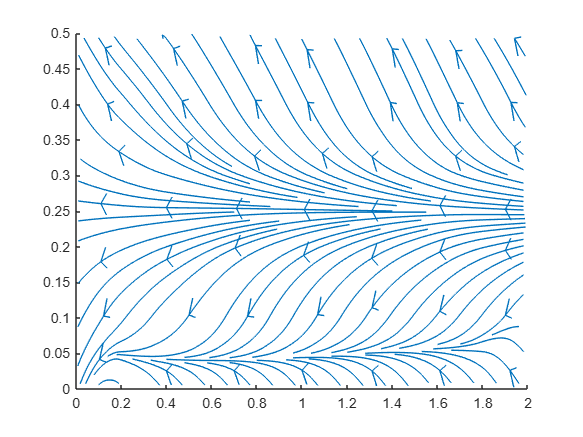

figure;
streamslice(XGrid, YGrid,-UX,-UY)
xlim([propStr.X0,propStr.XLx])
ylim([propStr.Y0,propStr.YLy])
hold off

## **Helper functions**

### **Element Stiffness Matrix and body force vector for quadrilateral elements**

function [K, F] = ...
    computeMasterStiffMatrixandForceVectorPlaneStress ...
    (msh, N, propStr)

**Function description**

Computation of the element stiffness matrix for an element based on the 2D plane stress theory with two degrees of freedom per node $\left(u,v\right)$, the horizontal and vertical deflections respectively.

**            Input :**

                  msh : Structure containing the nodes and the elements in a quadrilateral finite element mesh

                  `N` : Cell array containing the symbolic expression for the basis functions

      `propStr` : Structure containing the following fields,

                           `.t` : Thickness of the shell

                       `.p_x` : Uniformly distributed load in the x-direction along the boundary at X = XLx 

                       `.p_y` : Uniformly distributed load in the y-direction along the boundary at X = XLx 

                           `.E` : Young's modulus

                         `.nu` : Poisson's ratio

                           `.G` : Shear modulus

                           `.D` : Plate's stiffness

                   `.alpha` : Shear correction factor

**         Output :**

                 `K` : Master stiffness matrix of a plane stree membrane

                 `F` : Master force vector of a plane stress membrane 

**Function implementation**

Input validation

    arguments
        msh (1, 1) struct
        N (1, :) cell
        propStr (1, 1) struct 
    end

Read input

    numEl = length(msh.elements(:, 1));
    numNodes = length(msh.nodes(:, 1));
    numDOFs = 2*numNodes;

    X0 = min(msh.nodes(:,1));
    XLx = max(msh.nodes(:,1));
    Y0 = min(msh.nodes(:,2));
    YLy = max(msh.nodes(:,2));

Computation of the material matrix

    D = ((propStr.E)/(1-propStr.nu^2))*[1 propStr.nu 0
        propStr.nu 1 0
        0 0 (1-propStr.nu)/2];

Initialization of the global master stiffness matrix and master load vector

    K = zeros(numDOFs);
    F = zeros(numDOFs, 1);

Loop over all the elements in the mesh

    for ii = 1:numEl    

Get nodal indices and nodal coordinates

        id_nodes_el = msh.elements(ii, :);
        X = msh.nodes(id_nodes_el, 1:2);

        syms xi eta
        numNodesEl = height(X);
        numDOFsEl = 2*numNodesEl;

Formulation of the basis function's matrix

        Nmtx = sym(zeros(2, numDOFsEl));
        for jj = 1:numNodesEl
            % Nmtx(1, 3*ii - 2) = N{ii};
            Nmtx(1, 2*jj - 1) = N{jj};
            Nmtx(2, 2*jj) = N{jj};
        end

Formulation of the geometry map

        pos_vct(xi, eta) = transpose([N{:}]*X(:, 1:2));

Formulate the Jacobian matrix

        Jacobian_mtx(xi, eta) = jacobian(pos_vct, [xi eta]);

Compute the determinant of the Jacobian

        detJ(xi, eta) = simplify(det(Jacobian_mtx(xi, eta)));

Compute the derivatives of the basis functions with respect to the physical space in the parametric space

        dNdXY(xi, eta) = simplify(transpose(transpose(Jacobian_mtx(xi, eta)) ...
            \[diff([N{:}], xi); diff([N{:}], eta)]));

Formulate the B-operator matrix for the plane stress problem

        Bmtx = sym(zeros(3, numDOFsEl));
        for jj = 1:numNodesEl
            idx_vct_bf = zeros(1, numel(N));
            idx_vct_bf(1, jj) = 1;
            Bmtx(1, 2*jj - 1) = idx_vct_bf*dNdXY*[1; 0];
            Bmtx(2, 2*jj) = idx_vct_bf*dNdXY*[0; 1];
            Bmtx(3, 2*jj - 1) = idx_vct_bf*dNdXY*[0; 1];
            Bmtx(3, 2*jj) = idx_vct_bf*dNdXY*[1; 0];
        end

Formulate the integrand of the stiffness matrix and the body load vector for the plane stress problem

        KeInt(xi, eta) = propStr.t*transpose(Bmtx)*D*Bmtx*detJ;
        FeInt(xi, eta) = transpose(Nmtx)*[propStr.p_x; propStr.p_y]*detJ;

Compute the stiffness matrix for the plane stress problem

%     Ke = int(int(Ke_integrand, eta, -1, 1), xi, -1, 1);
        Ke = zeros(numDOFsEl);
    
        [xiGP, GWXi] = getGaussPointsAndWeightsOverUnitDomain(2);
        [etaGP, GWEta] = getGaussPointsAndWeightsOverUnitDomain(2);
        for kk = 1:height(GWEta)
            for ll = 1:height(GWXi)
                Ke = Ke + KeInt(xiGP(ll), etaGP(kk))*GWXi(ll)*GWEta(kk);
            end
        end

Compute the stiffness matrix with double precision

        Ke = double(Ke);

Element Freedom Table (EFT)

        EFT = [2*id_nodes_el-1; 2*id_nodes_el];
        EFT_K = EFT(:);

Assembly

        K(EFT_K, EFT_K) = K(EFT_K, EFT_K) + Ke;

        NoElY = length(unique(msh.nodes(:,2)))-1;
        LengthElY = (YLy-Y0)/NoElY;

        id_nodes_el = msh.elements(ii, :);
        X = msh.nodes(id_nodes_el, 1:2);
        Fe = [propStr.p_x*LengthElY/2; propStr.p_y*LengthElY/2];
        for jj = 1:length(X)
            if X(jj,1) == propStr.XLx
                EFT_F = EFT(:,jj);
                F(EFT_F) = F(EFT_F) + Fe ;
            end
        end
        F = double(F);
    end

end

## **Generation of a quadrilateral mesh**

function [nodesX, nodesY] = generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElx, numEly)

### Input validation

arguments
    X0 (1, 1) double
    XLx (1, 1) double
    Y0 (1, 1) double
    YLy (1, 1) double
    numElx (1, 1) double {mustBeInteger, mustBePositive}
    numEly (1, 1) double {mustBeInteger, mustBePositive}
end

### Generation of a structured discretization both along *X*- and *Y*-Cartesian directions

isMeshEquispaced = true; % Render the mesh non-equispaced
nodes_alongX = linspace(X0, XLx, numElx + 1)';
nodes_alongY = linspace(Y0, YLy, numEly + 1)';
if ~isMeshEquispaced
    nodes_alongX = [0 0.4 0.9 1.6 2]';
    nodes_alongY = [0 0.6 1]';
end
nodesX = repmat(nodes_alongX, 1, numEly + 1)';
nodesY = repmat(nodes_alongY, numElx + 1, 1);

### Render the mesh non-uniform by modifying some of the nodal coordinates (it only works for `numElx = 4` and `numEly = 2`)

isMeshUniform = true;
if ~isMeshUniform
    if numElx ~= 4 || numEly ~= 2
        error("Making the mesh non-uniform only works for numElx = 4 and numEly = 2")
    end
    % Move node 2
    nodesY(2, 1) = nodesY(2, 1) + 0.08; % y

    % Move node 5
    nodesX(2, 2) = nodesX(2, 2) + 0.08; % x
    nodesY(5, 1) = nodesY(5, 1) - 0.08; % y
    
    % Move node 8
    nodesX(2, 3) = nodesX(2, 3) - 0.08; % x
    nodesY(8, 1) = nodesY(8, 1) + 0.08; % y
    
    % Move node 11
    nodesX(2, 4) = nodesX(2, 4) + 0.08; % x
    nodesY(11, 1) = nodesY(11, 1) + 0.08; % x
    
    % Move node 14
    nodesY(14, 1) = nodesY(14, 1) - 0.08; % x
end
end

## **Generation of a bilinear quadrilateral mesh**

function msh = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesEl)

### Input validation

arguments
    numElx (1, 1) double {mustBeInteger, mustBePositive}
    numEly (1, 1) double {mustBeInteger, mustBePositive}
    numEl (1, 1) double {mustBeInteger, mustBePositive}
    nodesX (:, :) double
    nodesY (:, 1) double 
    numNodesEl (1, 1) double {mustBeInteger, mustBePositive}
end

### Assign the nodes of the quadrilateral bilinear mesh

msh.nodes = [nodesX(:) nodesY zeros(numel(nodesY), 1)];
msh.elements = zeros(numEl, numNodesEl);
counterEl = 1;
for ii = 1:numElx
    adv = (ii - 1)*(numEly + 1);
    advplus1 = ii*(numEly + 1);
    for jj = 1:numEly
        msh.elements(counterEl, :) = [jj+adv jj+adv+1 jj+advplus1+1 jj+advplus1];
        counterEl = counterEl + 1;
    end
end
end


### Getting Guass points

function [GP, GW] = getGaussPointsAndWeightsOverUnitDomain(numPts)
arguments
    numPts (1, 1) double {mustBeInteger, mustBePositive}
end

if numPts == 0
    GP = 0;
    GW = 0;
elseif numPts == 1
    GP = -0.000000000000000e-01;
    GW =  2.000000000000000e+00;
elseif numPts == 2
    GP = [5.773502691896258e-01; 
         -5.773502691896258e-01];
    GW = [1.000000000000000e+00;
          1.000000000000000e+00];
elseif numPts == 3
    GP = [ 7.745966692414834e-01;
           -0.000000000000000e-01;
           -7.745966692414834e-01];
    GW = [ 5.555555555555556e-01;
            8.888888888888889e-01;
            5.555555555555556e-01];
elseif numPts == 4
    GP = [  8.611363115940526e-01;
            3.399810435848563e-01;
           -3.399810435848563e-01;
           -8.611363115940526e-01];
    GW = [  3.478548451374539e-01;
            6.521451548625461e-01;
            6.521451548625461e-01;
            3.478548451374539e-01];
    end

end

function k=LineCurvature2D(Vertices,Lines)

This function calculates the curvature of a 2D line. It first fits 

polygons to the points. Then calculates the analytical curvature from

the polygons;

     k = LineCurvature2D(Vertices,Lines)

inputs,

  Vertices : A M x 2 list of line points.

  (optional)

  Lines : A N x 2 list of line pieces, by indices of the vertices

        (if not set assume Lines=[1 2; 2 3 ; ... ; M-1 M])

outputs,

  k : M x 1 Curvature values

% If no line-indices, assume a x(1) connected with x(2), x(3) with x(4) ...
if(nargin<2)
    Lines=[(1:(size(Vertices,1)-1))' (2:size(Vertices,1))'];
end

% Get left and right neighbor of each points
Na=zeros(size(Vertices,1),1); Nb=zeros(size(Vertices,1),1);
Na(Lines(:,1))=Lines(:,2); Nb(Lines(:,2))=Lines(:,1);

% Check for end of line points, without a left or right neighbor
checkNa=Na==0; checkNb=Nb==0;
Naa=Na; Nbb=Nb;
Naa(checkNa)=find(checkNa); Nbb(checkNb)=find(checkNb);

% If no left neighbor use two right neighbors, and the same for right... 
Na(checkNa)=Nbb(Nbb(checkNa)); Nb(checkNb)=Naa(Naa(checkNb));

% Correct for sampeling differences
Ta=-sqrt(sum((Vertices-Vertices(Na,:)).^2,2));
Tb=sqrt(sum((Vertices-Vertices(Nb,:)).^2,2)); 

% If no left neighbor use two right neighbors, and the same for right... 
Ta(checkNa)=-Ta(checkNa); Tb(checkNb)=-Tb(checkNb);

% Fit a polygons to the vertices 
% x=a(3)*t^2 + a(2)*t + a(1) 
% y=b(3)*t^2 + b(2)*t + b(1) 
% we know the x,y of every vertice and set t=0 for the vertices, and
% t=Ta for left vertices, and t=Tb for right vertices,  
x = [Vertices(Na,1) Vertices(:,1) Vertices(Nb,1)];
y = [Vertices(Na,2) Vertices(:,2) Vertices(Nb,2)];
M = [ones(size(Tb)) -Ta Ta.^2 ones(size(Tb)) zeros(size(Tb)) zeros(size(Tb)) ones(size(Tb)) -Tb Tb.^2];
invM=inverse3(M);
a(:,1)=invM(:,1,1).*x(:,1)+invM(:,2,1).*x(:,2)+invM(:,3,1).*x(:,3);
a(:,2)=invM(:,1,2).*x(:,1)+invM(:,2,2).*x(:,2)+invM(:,3,2).*x(:,3);
a(:,3)=invM(:,1,3).*x(:,1)+invM(:,2,3).*x(:,2)+invM(:,3,3).*x(:,3);
b(:,1)=invM(:,1,1).*y(:,1)+invM(:,2,1).*y(:,2)+invM(:,3,1).*y(:,3);
b(:,2)=invM(:,1,2).*y(:,1)+invM(:,2,2).*y(:,2)+invM(:,3,2).*y(:,3);
b(:,3)=invM(:,1,3).*y(:,1)+invM(:,2,3).*y(:,2)+invM(:,3,3).*y(:,3);

% Calculate the curvature from the fitted polygon
k = 2*(a(:,2).*b(:,3)-a(:,3).*b(:,2)) ./ ((a(:,2).^2+b(:,2).^2).^(3/2));

function  Minv  = inverse3(M)
% This function does inv(M) , but then for an array of 3x3 matrices
adjM(:,1,1)=  M(:,5).*M(:,9)-M(:,8).*M(:,6);
adjM(:,1,2)=  -(M(:,4).*M(:,9)-M(:,7).*M(:,6));
adjM(:,1,3)=  M(:,4).*M(:,8)-M(:,7).*M(:,5);
adjM(:,2,1)=  -(M(:,2).*M(:,9)-M(:,8).*M(:,3));
adjM(:,2,2)=  M(:,1).*M(:,9)-M(:,7).*M(:,3);
adjM(:,2,3)=  -(M(:,1).*M(:,8)-M(:,7).*M(:,2));
adjM(:,3,1)=  M(:,2).*M(:,6)-M(:,5).*M(:,3);
adjM(:,3,2)=  -(M(:,1).*M(:,6)-M(:,4).*M(:,3));
adjM(:,3,3)=  M(:,1).*M(:,5)-M(:,4).*M(:,2);
detM=M(:,1).*M(:,5).*M(:,9)-M(:,1).*M(:,8).*M(:,6)-M(:,4).*M(:,2).*M(:,9)+M(:,4).*M(:,8).*M(:,3)+M(:,7).*M(:,2).*M(:,6)-M(:,7).*M(:,5).*M(:,3);
Minv=bsxfun(@rdivide,adjM,detM);
end
end


function [hLeg, levMat] = contourLegend(hCont, txtCont, locLeg, hOther, ...
  txtOther, posOther)
% [hLeg, levMat] = contourLegend(hCont, txtCont, locLeg, hOther, txtOther, ...
%   posOther)
% Adds a curve description legend to a contour plot. The default description is
% the level, but you may optionally supply custom descriptions. You might also
% include descriptions of other plotted objects in the legend.
%
% INPUT:
% hCont    - a handle, or a vector of handles, to contour object(s) in the same
%            plot.
% txtCont  - an optional cell vector with strings that describes the curves,
%            should have as many items as levels ("type" = 'curves') and fill
%            intervals ("type" = 'filled'). Default descriptions are the curve
%            levels and fill intervals. Use the function with the "locLeg"
%            option 'notdrawn' to get the current levels and fill intervals from
%            "levMat".
% locLeg   - an optional string with the location of the legend. For available
%            options see help for "legend". Also supported is 'notdrawn' that
%            will not add a legend. Default is 'best'.
% hOther   - an optional handle, or a vector of handles, to other graphics
%            objects in the plot that you want to include in the legend.
%            Default is empty.
% txtOther - an optional cell vector with strings that describes the other
%            items above. Must be supplied if "hOther" is given and have as
%            many items as the length of "hOther". Default is empty.
% posOther - an optional string 'b(efore)' or 'a(fter)' that determines if the
%            description of other graphic objects comes before or after the
%            descriptions of the contours in the legend. Default is 'after'.
% 
% OUTPUT:
% hLeg     - a handle to the legend object. Use this to change the position,
%            fonts etc. for the legend.
% levMat   - a two column matrix with the contour levels limits in each row.
%            Equal limits indicate a contour curve and unequal a filled area.
%
% NOTE 1: The colors for the contours in the legend will NOT be updated if they
%         are changed in the plot, for example by changing the color map. It is
%         recommended that the legend is added after all plotting is done.
% NOTE 2: There is a strange bug, at least in R2020a. The contour levels
%         shown in the tooltip, if you click on a contour curve, will not the
%         match the levels in the legend (and the ones returned in the contour
%         data matrix).
%
% EXAMPLE:
% [X, Y, Z]  = peaks(512);
% figure
% [~, hCont] = contour(X, Y, Z, 'LineWidth', 1.5);
% contourLegend(hCont)
% figure
% [~, hCont] = contourf(X, Y, Z);
% contourLegend(hCont)
%
% See also contour, contourf, clabel, legend
%
% Version 1.1, 2022. Patrik Forssén, Karlstad University.
% Version History
% Version 1.1: Remove type and used hidden property instead
 
% Default input
if (nargin < 2), txtCont   = []; end
if (nargin < 3 || isempty(locLeg))  , locLeg   = 'best' ; end
if (nargin < 4), hOther   = []; end
if (nargin < 5), txtOther = []; end
if (nargin < 6 || isempty(posOther)), posOther = 'after'; end
 
% Default output
hLeg = [];
 
% Check input
hCont   = hCont(:);
hOther  = hOther(:);
[hAx, locLeg, hOther, txtOther, posOther] = checkInput(...
  hCont, txtCont, locLeg, hOther, txtOther, posOther);
 
% Get contour curve specification
curveSpec = contourCurves(hCont);
 
% Set 'flat' to a color specification
curveSpec = flat2color(hAx, curveSpec);
 
% Get handles to curve specification invisible dummy lines or patches
[hCurve, txtCurve, levMat] = getCurveHandles(hAx, curveSpec, txtCont);
 
% Draw legend
if (~strcmp(locLeg, 'notdrawn'))
  hLeg = drawLeg(hAx, locLeg, hCurve, txtCurve, hOther, txtOther, posOther);
end
 
% Output
if (nargout == 0)
  clear hLeg
end
 
end
 
 
 
function hLeg = drawLeg(hAx, locLeg, hCurve, txtCurve, hOther, txtOther, ...
  posOther)
 
hItem   = hCurve;
txtItem = txtCurve;
if (~isempty(hOther))
  % Add
  switch posOther
    case 'before'
      hItem   = [hOther  ; hItem];
      txtItem = [txtOther; txtItem];
    case 'after'
      hItem   = [hItem  ; hOther];
      txtItem = [txtItem; txtOther];
  end
end
 
% Draw the legend
hLeg = legend(hAx, hItem, txtItem, 'Location', locLeg);
 
end
 
 
 
function [hCurve, txtCurve, levMat] = getCurveHandles(hAx, curveSpec, ...
  txtCont)
 
% Function name
funName = mfilename;
 
% Number of curves
nCurves  = size(curveSpec, 1);
% Unique levels
unLev  = unique(cell2mat(curveSpec(:, 1)));
levMat = [];
for curveNo = 1 : nCurves
  currLev  = curveSpec{curveNo, 1};
  currType = curveSpec{curveNo, 5};
  switch currType
    case 'curves'
      levMat = [levMat; currLev, currLev];
    case 'filled'
      currLevInd = find(unLev == currLev, 1, 'first');
      if (currLevInd == length(unLev))
        levMat = [levMat; currLev, inf];
      else
        levMat = [levMat; currLev, unLev(currLevInd+1)];
      end
  end
end
levMat = unique(levMat, 'rows');
levMat = sortrows(levMat, [1 2]);
 
% Make a default text cell
unLevCell = cell(size(levMat, 1), 1);
for levNo = 1 : size(levMat, 1)
  currInt = levMat(levNo, :);
  if (currInt(1) == currInt(2))
    unLevCell{levNo} = num2str(currInt(1));
  else
    if (~isfinite(currInt(2)))
      unLevCell{levNo} = ['> ', num2str(currInt(1))];
    else
      unLevCell{levNo} = [num2str(currInt(1)), ' to ', num2str(currInt(2))];
    end
  end
end
 
% Check legTxt if supplied
nUn = size(levMat, 1);
if (~isempty(txtCont))
  if (length(txtCont) > nUn)
    warnStr = ['Input 3, "txtCont", contains to many strings (should ', ...
      'contain ', num2str(nUn), '). Extra entries will be ignored'];
    warning([funName, ':TooManyStrings'], warnStr)
    txtCont = txtCont(1:nUn);
  elseif (length(txtCont) < nUn)
    warnStr = ['Input 3, "txtCont", contains too few strings (should ', ...
      'contain ', num2str(nUn), '). Will use default for missing items'];
    warning([funName, ':TooFewStrings'], warnStr)
    txtCont(end+1:nUn) = unLevCell(length(txtCont)+1:end);
  end
else
  % Default
  txtCont = unLevCell;
end
 
% Plot dummy lines/patches
hold(hAx, 'on');
txtCurve = cell(nCurves, 1);
hCurve   = gobjects(nCurves, 1);
nanVec   = [NaN, NaN, NaN, NaN];
for curveNo = 1 : nCurves
  currCurve = curveSpec(curveNo, :);
  currLev   = currCurve{1};
  switch currCurve{5}
    case 'curves'
      levInd = find(levMat(:, 1) == currLev & levMat(:, 2) == currLev, ...
        1, 'first');
      hCurve(curveNo) = plot(hAx, NaN, 'LineStyle', currCurve{2}, ...
        'LineWidth', currCurve{3}, 'Color', currCurve{4});
    case 'filled'
      levInd = find(levMat(:, 1) == currLev & levMat(:, 2) > currLev, ...
        1, 'first');
      hCurve(curveNo) = patch(hAx, nanVec, nanVec, currCurve{4});
  end
  txtCurve{curveNo} = txtCont{levInd};
end
 
end
 
 
 
function curveSpec = flat2color(hAx, curveSpec)
% Unique levels
unLev = unique(cell2mat(curveSpec(:, 1)));
 
% Get color mapping
colMap = hAx.Colormap;
nCol   = size(colMap, 1);
colLim = hAx.CLim;
 
if (length(unLev) == 1)
  % Special, uses the middle color
  colNo = round(nCol/2);
else
  % Linear interpolation
  pp    = polyfit(colLim, [1 nCol], 1);
  colNo = round(polyval(pp, unLev));
end
% Possibly map to last and first color
colNo(unLev < colLim(1))   = 1;
colNo(unLev > colLim(end)) = nCol;
% Safeguard...
colNo(colNo < 1   ) = 1;
colNo(colNo > nCol) = nCol;
 
% Curves with 'flat'
flatInd = find(cellfun(@ischar, curveSpec(:, 4)));
for flatNo = flatInd(:)'
  levNo = find(curveSpec{flatNo, 1} == unLev, 1, 'first');
  curveSpec{flatNo, 4} = colMap(colNo(levNo), :);
end
 
% Only want unique rows
curveSpec = uniqueCellRows(curveSpec);
 
end
 
 
 
function curveSpec = contourCurves(hCont)
% Must be called...
drawnow
 
% Column 1 : level
% Column 2 : LineStyle
% Column 3 : LineWidth
% Column 4 : LineColor ('flat' or RGB triplet)
% Column 5 : type
curveSpec = cell(0, 5);
for objNo = 1 : length(hCont)
  currObj     = hCont(objNo);
  lineStyle   = currObj.LineStyle;
  lineWidth   = currObj.LineWidth;
  if (~isempty(currObj.FacePrims))
    % Undocumented!
    type      = 'filled';
    lineColor = 'flat';
  else
    type      = 'curves';
    lineColor = currObj.LineColor;
  end
  levVec      = currObj.LevelList;
  for levNo = 1 : length(levVec)
    currLev   = levVec(levNo);
    cellRow   = {currLev, lineStyle, lineWidth, lineColor, type};
    curveSpec = [curveSpec; cellRow]; 
  end
end
 
% Only want unique rows
curveSpec = uniqueCellRows(curveSpec);
 
end
 
 
 
function [CU, keepInd, rmMap] = uniqueCellRows(C)
% Get unique cell rows
 
nRows = size(C, 1);
rmMap = 1 : nRows;
rmInd = [];
for refNo = 1 : nRows
  if (ismember(refNo, rmInd)), continue, end
  refRow = C(refNo, :);
  for compNo = refNo+1 : nRows
    if (ismember(compNo, rmInd)), continue, end
    compRow = C(compNo, :);
    if (isequal(refRow, compRow))
      rmInd = [rmInd; compNo];
      rmMap(compNo) = refNo;
    end
  end
end
 
% Trim
keepInd = setdiff(1:nRows, rmInd);
CU = C(keepInd, :);
 
end
 
 
 
%--------------------------------CHECK INPUT------------------------------------
function [hAx, locLeg, hOther, txtOther, posOther] = checkInput(...
  hCont, txtCont, locLeg, hOther, txtOther, posOther)
 
% Function name
funName = mfilename;
 
% 1: hCont
errStr = ['Input 1, "hCont", should be graphic handle(s) to ', ...
  'contour objects in the same plot'];
if (any(~ishandle(hCont)))
  error([funName, ':WrongInput'], errStr)
end
iscontour = @(h) isgraphics(h, 'contour');
if (any(~iscontour(hCont)))
  error([funName, ':WrongInput'], errStr)
end
[res, hAx] = checkSameAxes(hCont);
if (~res)
  error([funName, ':WrongInput'], errStr)
end
  
% 2: txtCont
if (~isempty(txtCont))
  if (ischar(txtCont)), txtCont = {txtCont}; end
  txtCont = txtCont(:);
  errStr  = 'Input 2, "txtCont", should be a cell array with strings';
  tFun    = @(x) ischar(x) & isvector(x);
  if (any(~cellfun(tFun, txtCont)))
    error([funName, ':WrongInput'], errStr)
  end
end
 
% 3: locLeg
validStr = {...
  'north'
  'south'
  'east'
  'west'
  'northeast'
  'northwest'
  'southeast'
  'southwest'
  'northoutside'
  'southoutside'
  'eastoutside'
  'westoutside'
  'northeastoutside'
  'northwestoutside'
  'southeastoutside'
  'southwestoutside'
  'best'
  'bestoutside'
  'none'
  'notdrawn'};
errStr = 'Input 3, "locLeg", should be a valid legend position string';
if (~ischar(locLeg) && ~isvector(locLeg))
  error([funName, ':WrongInput'], errStr)
end
locLeg = validatestring(locLeg, validStr, funName, 'locLeg', 3);
 
% 4: hOther
if (~isempty(hOther))
  errStr = ['Input 4, "hOther", should be graphic handle(s) to ', ...
    'objects in the same plot as the contours'];
  if (any(~ishandle(hOther)))
    error([funName, ':WrongInput'], errStr)
  end
  if (~checkSameAxes(hOther, hAx))
    error([funName, ':WrongInput'], errStr)
  end
  
  % 5: txtOther
  if (ischar(txtOther)), txtOther = {txtOther}; end
  txtOther = txtOther(:);
  errStr   = 'Input 5, "txtOther", should be a cell array with strings';
  tFun     = @(x) ischar(x) & isvector(x);
  if (any(~cellfun(tFun, txtOther)))
    error([funName, ':WrongInput'], errStr)
  end
  if (length(txtOther) > length(hOther))
    warnStr = ['Input 5, "txtOther", contains to many strings (should ', ...
      'contain ', num2str(length(hOther)), '). Extra entries will be ignored'];
    warning([funName, ':TooManyStrings'], warnStr)
    txtOther = txtOther(1:length(hOther));
  elseif (length(txtOther) < length(hOther))
    warnStr = ['Input 5, "txtOther", contains too few strings (should ', ...
      'contain ', num2str(length(hOther)), '). Missing items will be ignored'];
    warning([funName, ':TooFewStrings'], warnStr)
    hOther = hOther(1:length(txtOther));
  end
  
  % 6: posOther
  validStr = {'before', 'after'};
  errStr   = 'Input 6, "posOther", should be string ''before'' or ''after''';
  if (~ischar(posOther) && ~isvector(posOther))
    error([funName, ':WrongInput'], errStr)
  end
  posOther = validatestring(posOther, validStr, funName, 'posOther', 6);
end
 
end
 
 
 
function [res, hAx] = checkSameAxes(hVec, hAx)
% Checks if graphic objects belong to the same axes
 
% Default input
if (nargin < 2), hAx = []; end  % Reference axes
 
hVec    = hVec(:);
axesVec = gobjects(1, length(hVec)+length(hAx));
for objNo = 1 : length(hVec)
  currObj = hVec(objNo);
  while (1)
    parent = currObj.Parent;
    if (strcmp(parent.Type, 'axes'))
      axesVec(objNo) = parent;
      break
    elseif (strcmp(parent.Type, 'root'))
      % All the way up to the root
      res = false;
      return
    end
    currObj = parent;
  end
end
if (isempty(axesVec)) , return, end
if (~isempty(hAx)), axesVec(end) = hAx; end
 
% Check if all axes are the same
res   = true;
refAx = axesVec(1);
for axNo = 2 : length(axesVec)
  currAx = axesVec(axNo);
  if (~isequal(refAx, currAx))
    res = false;
    return
  end
end
 
% Set output
hAx = axesVec(1);
 
end

## References

[[1] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)

[](https://doi.org/10.1007/978-3-540-78319-0)[[2] Brezzi, F., Boffi, D., Demkowicz, L., Durán, R. G., Falk, R. S., & Fortin, M. (2008). Mixed finite elements, compatibility conditions, and applications. *Springer*, *2*, 4-2.](https://doi.org/10.1007/978-3-540-78319-0)

## References

[[1] Holzer, Stefan, Ernst Rank, and Heinrich Werner. "An implementation of the hp‐version of the finite element method for Reissner‐Mindlin plate problems." *International Journal for Numerical Methods in Engineering* 30.3 (1990): 459-471.](https://onlinelibrary.wiley.com/doi/abs/10.1002/nme.1620300306)